% 创建基于进程的进程池
%{
poolobj = gcp('nocreate'); % If no pool, do not create new one.
if isempty(poolobj)
    poolobj = parpool('Processes',2);
end
%}
obj = bridge_state;
% 先输出mac文件
[Pz_final,bridge,data_container,workspace,W,Maps_Base,X_sorted_points,L_undeformed] = outputTask(obj);

ans = logical
   1


% 并行两个函数
%{
time_before = datetime('now');
MaxIter = 5;
future_optim = parfeval(poolobj,@OptimTask,4,Pz_final,bridge,data_container,workspace,W,Maps_Base,X_sorted_points,MaxIter,L_undeformed) % 优化进程

函数或变量 'poolobj' 无法识别。

future_ansys = parfeval(poolobj,@AnsysTask,2,obj) % 计算进程
% 并行的两个函数的结果
[status,cmdout] = fetchOutputs(future_ansys);
[x, fval, exitflag, output] = fetchOutputs(future_optim);
% delete(gcp('nocreate'))
time_after = datetime('now');
time_diff = time_after - time_before;
%}

% 运行OptimTask
time_before = datetime('now');
MaxIter = 1;
[x, fval, exitflag, output]  = OptimTask(Pz_final,bridge,data_container,workspace,W,Maps_Base,X_sorted_points,MaxIter,L_undeformed) % 优化进程

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      14    7.783359e+13    0.000e+00    1.000e+07

求解器过早停止。

fmincon 已停止，因为它超过函数计算限制，
options.MaxFunctionEvaluations = 1.000000e+00。



x = 1.0e+06 *

    2.0995    2.5594    2.9280    2.3799    2.8859    1.9948    1.8881    1.9948    2.8859    2.3799    2.9280    2.5594    2.1095


fval = 7.7834e+13

exitflag = 0

output = 包含以下字段的 struct :
         iterations: 0
          funcCount: 14
    constrviolation: 0
           stepsize: 0
          algorithm: 'interior-point'
      firstorderopt: 1.0004e+07
       cgiterations: 0
            message: '求解器过早停止。↵↵fmincon 已停止，因为它超过函数计算限制，↵options.MaxFunctionEvaluations = 1.000000e+00。'
       bestfeasible: [1×1 struct]


time_after = datetime('now');
time_diff = time_after - time_before;

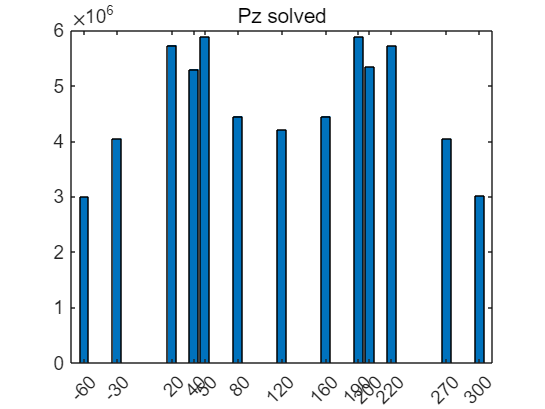

Pz_solved = data_container.Data.Map_Pz_solved(100);

bar(obj.XCoordOfPz,Pz_solved)
title('Pz solved')

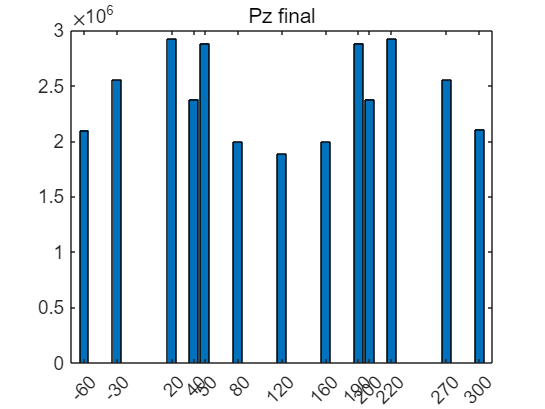


bar(obj.XCoordOfPz,Pz_final)
title('Pz final')


Pz_solved ./ Pz_final

ans =     1.4287    1.5834    1.9587    2.2275    2.0417    2.2322    2.2306    2.2327    2.0414    2.2448    1.9584    1.5826    1.4300


function [Pz_final,bridge,data_container,workspace,W,Maps_Base,X_sorted_points,L_undeformed] = outputTask(obj)
    
    bridge = obj.clone();
    % 输出BaseModel
    outputBaseModel(bridge)
    % 在MATLAB中恢复为CableSystem
    resumeCableSystem(bridge)
    % 主缆找形、根据最优设计竖向力Pz_final计算主缆线形和内力、吊索内力
    Pz_final = bridge.Result_Iteration.Iter_Pz(bridge.Iter_Optimization);
    Y_0 = bridge.solveCableShape(Pz_final);
    % 存储数据
    data_container = DataContainer();
    data_container.Data.Y_0 = Y_0;
    data_container.Data.Map_Pz_solved = containers.Map("KeyType",'double','ValueType','any');
    data_container.Data.count_ObjFunc = 0;
    data_container.Data.Pz_target = Pz_final;
    % 最优设计竖向力Pz_final计算斜拉索内力
    X_Pz = bridge.XCoordOfPz;
    for i=1:length(bridge.ReplacedStayedCable)
        stayed_cable = bridge.ReplacedStayedCable(i);
        Point_Bottom = stayed_cable.findGirderPoint();
        X_Bottom = [Point_Bottom.X];
        P_girder_z = zeros(1,length(X_Bottom));
        for j=1:length(X_Pz)
            index = abs(X_Pz(j)-X_Bottom) < 1e-5;
            P_girder_z(index) = Pz_final(j);
        end
        stayed_cable.getP(P_girder_z);
    end
    % 输出CableSystem
    Maps_Base = {bridge.Params.Map_OutputedPoint,...
                 bridge.Params.Map_MatlabLine2AnsysLine,bridge.Params.Map_AnsysLine2MatlabLine,...
                 bridge.Params.Map_MatlabLine2AnsysElem,bridge.Params.Map_AnsysElem2MatlabLine};
    bridge.Params.Map_OutputedPoint = cloneMap(Maps_Base{1});
    bridge.Params.Map_MatlabLine2AnsysLine = cloneMap(Maps_Base{2});
    bridge.Params.Map_AnsysLine2MatlabLine = cloneMap(Maps_Base{3});
    bridge.Params.Map_MatlabLine2AnsysElem = cloneMap(Maps_Base{4});
    bridge.Params.Map_AnsysElem2MatlabLine = cloneMap(Maps_Base{5});
    outputCableSystem(bridge);
    % 根据设计竖向力的顺序，排列与之相关的
    Map_elem = bridge.Params.Map_MatlabLine2AnsysElem;
    points = [];
    lines = [];
    qs = [];
    Areas = [];
    StrucutreList = bridge.StructureList;
    for i=1:length(StrucutreList)
        structure = StrucutreList{i};
        if strcmp(class(structure),'StayedCable') || strcmp(class(structure),'Hanger')
            points = [points,structure.findGirderPoint];
            lines = [lines,structure.Line];
            qs = [qs,structure.Material.MaterialData.gamma*ones(size(structure.Line))];
            Areas = [Areas,structure.Section.Area];
        else
            continue
        end
    end
    [sorted_points,index] = points.sort('X');
    X_sorted_points = [sorted_points.X];
    sorted_lines = lines(index);
    num_elem = cell2mat(values(Map_elem,num2cell([sorted_lines.Num])));
    bridge.outputAnsysIPC(num_elem);
    
    sorted_qs = qs(index);
    sorted_Areas = Areas(index);
    W = sorted_Areas.*sorted_qs;
    [delta_x,delta_y,delta_z] = sorted_lines.DeltaLength();
    L_undeformed = sqrt(delta_x.^2 + delta_y.^2 + delta_z.^2);
    workspace = bridge.OutputMethod.WorkPath;
    % 运行BaseModel
    obj.run('JobName','BaseModel',...
            'MacFilePath',fullfile(workspace,'main_Base.mac'),...
            'ResultFilePath',fullfile(workspace,'Result_BaseModel.out'));
end

function  [x,fval,exitflag,output] = OptimTask(Pz_final,bridge,data_container,workspace,W,Maps_Base,X_sorted_points,MaxIter,L_undeformed)
    
    % 优化设置
    lb = zeros(size(Pz_final));
    %{
    X_Pz = bridge.XCoordOfPz;
    for i=1:length(X_Pz)
        index = abs(X_Pz(i)-X_sorted_points)<=1e-3;
        lb(i) = sum(L_undeformed(index).*W(index))/2;
    end
    %}
    ub = 5*max(abs(Pz_final)) + zeros(size(Pz_final));
    func = @(Pz) ObjFunc(Pz,bridge,data_container,workspace,W,Maps_Base,X_sorted_points);
    %{
    options = optimoptions('fmincon',...
                           'Display','iter-detailed',...
                           'ObjectiveLimit',0.01,...
                           'DiffMinChange',0.01*min(abs(Pz_final)),...
                           'MaxFunctionEvaluations',(length(Pz_final)+1)*MaxIter);
    %}
    options = optimoptions('fmincon',...
                           'Display','iter-detailed',...
                           'ObjectiveLimit',0.01,...
                           'DiffMinChange',0.01*min(abs(Pz_final)),...
                           'MaxFunctionEvaluations',MaxIter);
    [x,fval,exitflag,output] = fmincon(func,Pz_final, [], [], [], [], lb, ub, [], options);
    
    
    % 优化完成之后
    % 通知ANSYS：已经优化完成，你也可以退出循环了
    outputStatus(workspace,"MATLAB_Call_ANSYS_Analyze.txt",-1);
    if exitflag > 0
        outputStatus(workspace,"MATLAB_Good_End",1);% 优化正常结束
    else
        outputStatus(workspace,"MATLAB_Bad_End",-1);% 优化发生错误
    end
end

function [status,cmdout] = AnsysTask(obj) % 负责调用ANSYS软件进行分析
    workspace = obj.OutputMethod.WorkPath;
    % 运行IPC_ANSYS.mac
    [status,cmdout] = obj.run('ComputingMode','Distributed',...
                                'JobName','TotalModel',...
                                'MacFilePath',fullfile(workspace,'IPC_ANSYS.mac'),...
                                'ResultFilePath',fullfile(workspace,'TotalModel.out'));
    if exist(fullfile(workspace,'TotalModel.lock'),'file')
        delete(fullfile(workspace,'TotalModel.lock'))
    end
end

function f = ObjFunc(Pz,obj,data_container,workspace,W,Maps_Base,X_elem)
    % 计算吊索力和主缆内力
    Y_final = obj.solveCableShape(Pz,data_container.Data.Y_0);
    data_container.Data.Y_0 = Y_final;
    
    % 计算斜拉索索力
    X_Pz = obj.XCoordOfPz;
    for i=1:length(obj.ReplacedStayedCable)
        stayed_cable = obj.ReplacedStayedCable(i);
        Point_Bottom = stayed_cable.findGirderPoint();
        X_Bottom = [Point_Bottom.X];
        P_girder_z = zeros(1,length(X_Bottom));
        for j=1:length(X_Pz)
            index = abs(X_Pz(j)-X_Bottom) < 1e-5;
            P_girder_z(index) = Pz(j);
        end
        stayed_cable.getP(P_girder_z);
    end
    % 将BaseModel的Map复制一份
    obj.Params.Map_OutputedPoint = cloneMap(Maps_Base{1});
    obj.Params.Map_MatlabLine2AnsysLine = cloneMap(Maps_Base{2});
    obj.Params.Map_AnsysLine2MatlabLine = cloneMap(Maps_Base{3});
    obj.Params.Map_MatlabLine2AnsysElem = cloneMap(Maps_Base{4});
    obj.Params.Map_AnsysElem2MatlabLine = cloneMap(Maps_Base{5});

    % outputCableSystem()中改变obj.Params.Map而不是Map_BaseModel
    outputCableSystem(obj);
    
    % 通知ANSYS，让其开始分析
    outputStatus(workspace,"MATLAB_Call_ANSYS_Analyze.txt",1); % ANSYS会将通知文件阅后即焚

    % MATLAB挂起，直到收到ANSYS通知
    waitForStatus(workspace,"ANSYS_Call_MATLAB_ObjFunc.txt");

    % ANSYS收到消息
    % ANSYS导入实常数
    % ANSYS进行一次分析
    % ANSYS输出Result.txt
    % ANSYS通知MATLAB，让其计算目标函数
    % ANSYS挂起

    
    % MATLAB收到ANSYS通知，通知文件阅后即焚
    if exist(fullfile(workspace,'ANSYS_Call_MATLAB_ObjFunc.txt'), 'file')
        delete(fullfile(workspace,"ANSYS_Call_MATLAB_ObjFunc.txt"))
    else
        error('ANSYS在时间内没有回调')
    end
    
    
    % 读入Result.txt
    RawData = inputData(workspace,"Result.txt",length(X_elem));
    
    force = RawData(1,:);
    INodeX = RawData(2,:);
    INodeY = RawData(3,:);
    INodeZ = RawData(4,:);
    JNodeX = RawData(5,:);
    JNodeY = RawData(6,:);
    JNodeZ = RawData(7,:);
    assignin("base","force",force)
    assignin("base","INodeX",INodeX)
    assignin("base","INodeY",INodeY)
    assignin("base","INodeZ",INodeZ)
    assignin("base","JNodeX",JNodeX)
    assignin("base","JNodeY",JNodeY)
    assignin("base","JNodeZ",JNodeZ)
    
    L = sqrt((INodeX-JNodeX).^2 + (INodeY-JNodeY).^2 + (INodeZ-JNodeZ).^2);
    assignin("base","L",L)
    Pz_solved = zeros(size(Pz));
    force_vertical = force.*abs(JNodeZ-INodeZ)./(L);
    for i=1:length(X_Pz)
        index = abs(X_Pz(i)-X_elem)<=1e-3;
        % Pz_solved(i) = sum(force_vertical(index) - L(index).*W(index)/2);
        Pz_solved(i) = sum(force_vertical(index));
    end
    assignin("base","X_elem",X_elem)
    assignin("base","W",W)
    assignin("base","Pz_solved",Pz_solved)

    % 计算优化目标：与优化目标之间的MSE
    Pz_target = data_container.Data.Pz_target;
    f = sum((Pz_target-Pz_solved).^2);

    % 存储数据
    count = data_container.Data.count_ObjFunc + 1;
    data_container.Data.count_ObjFunc = count;
    data_container.Data.Map_Pz_solved(count) = Pz_solved;
end

function data = inputData(folderPath, fileName, count_row, everyPauseSeconds, maxPauseSeconds)
    arguments
        folderPath {mustBeText}
        fileName {mustBeText}
        count_row {mustBeInteger}
        everyPauseSeconds {mustBeNumeric} = 0.005
        maxPauseSeconds {mustBeNumeric} = 10
    end
    % 数据文件路径
    dataFilePath = fullfile(folderPath, fileName);
    % lock文件路径
    splitted_filePath = strsplit(dataFilePath,'.');
    splitted_filePath(end) = {'.readlock'};
    readLockFilePath = strjoin(splitted_filePath,'');
    splitted_filePath(end) = {'.writelock'};
    writeLockFilePath = strjoin(splitted_filePath,'');
    % 1. 等待数据文件生成
    tic;
    while (~exist(dataFilePath, 'file')) || (exist(readLockFilePath,'file')) || (exist(writeLockFilePath,'file')) % 如果不存在、正在写出、正在写入文件，就等待
        pause(everyPauseSeconds);
        waitedSeconds = toc;
        if waitedSeconds > maxPauseSeconds
            disp(strcat('等待',dataFilePath,'时间超过', num2str(maxPauseSeconds), '秒'));
            break;
        end
    end
    % 2. 增加lock文件
    fileID = fopen(readLockFilePath, 'w');
    fclose(fileID);
    % 3. 读入数据文件
    fileID = fopen(dataFilePath, 'r');
    data = fscanf(fileID,'%e %e %e %e %e %e %e\n',[7,count_row]);
    fclose(fileID);
    % 4. 删除lock文件
    delete(readLockFilePath);
end

function outputStatus(folderPath, fileName, status, everyPauseSeconds, maxPauseSeconds)
    arguments
        folderPath {mustBeText}
        fileName {mustBeText}
        status = []
        everyPauseSeconds {mustBeNumeric} = 0.005
        maxPauseSeconds {mustBeNumeric} = 10
    end
    statusFilePath = fullfile(folderPath, fileName);
    % lock文件路径
    splitted_filePath = strsplit(statusFilePath,'.');
    splitted_filePath(end) = {'.readlock'};
    readLockFilePath = strjoin(splitted_filePath,'');
    splitted_filePath(end) = {'.writelock'};
    writeLockFilePath = strjoin(splitted_filePath,'');
    % 1. Lock文件删除
    tic;
    while (exist(readLockFilePath,'file')) || (exist(writeLockFilePath,'file'))
        pause(everyPauseSeconds);
        waitedSeconds = toc;
        if waitedSeconds > maxPauseSeconds
            disp(strcat('等待',statusFilePath,'时间超过', num2str(maxPauseSeconds), '秒'));
            break;
        end
    end
    % 2. 增加lock文件
    fileID = fopen(writeLockFilePath, 'w');
    fclose(fileID);
    if isempty(status)
        fileID = fopen(statusFilePath, 'w');
        fclose(fileID);
    elseif length(status)==1
        fileID = fopen(statusFilePath, 'w');
        fprintf(fileID, '%20.8E', status);
        fclose(fileID);
    end
    % 4. 删除lock文件
    delete(writeLockFilePath);
end

function waitForStatus(folderPath, fileName, everyPauseSeconds, maxPauseSeconds)
    arguments
        folderPath {mustBeText}
        fileName {mustBeText}
        everyPauseSeconds {mustBeNumeric} = 0.005
        maxPauseSeconds {mustBeNumeric} = 10
    end
    % 状态文件路径
    statusFilePath = fullfile(folderPath, fileName);
    % lock文件路径
    splitted_filePath = strsplit(statusFilePath,'.');
    splitted_filePath(end) = {'.readlock'};
    readLockFilePath = strjoin(splitted_filePath,'');
    splitted_filePath(end) = {'.writelock'};
    writeLockFilePath = strjoin(splitted_filePath,'');
    % 等待状态文件生成
    flag = true;
    tic;
    while (~exist(statusFilePath, 'file')) || (exist(readLockFilePath,'file')) || (exist(writeLockFilePath,'file'))
        pause(everyPauseSeconds);
        waitedSeconds = toc;
        if waitedSeconds > maxPauseSeconds
            fprintf('等待%s的时间超过%f秒，退出等待。\n',fileName,maxPauseSeconds);
            flag = false;
            break;
        end
    end
end

function outputBaseModel(obj)
    OutputMethod = obj.OutputMethod;
    OutputMethod.JobName = 'BaseModel';

    obj.OutputMethod.OutputObj = obj.OriginalBridge;
    OutputMethod.outputElementType();
    OutputMethod.outputMaterial();
    OutputMethod.outputSection();

    obj.OutputMethod.OutputObj = obj;
    OutputMethod.outputReal();
    OutputMethod.outputKeyPoint();
    OutputMethod.outputLine();
    OutputMethod.outputLineAttribution();
    OutputMethod.outputLineMesh();
    OutputMethod.outputConstraint();
    OutputMethod.outputCoupling();

    OutputMethod.outputMain('main_Base.mac','flag_Load',false,'flag_Solve',false);
end

function resumeCableSystem(obj)
    % 隐藏梁塔及其荷载和约束
    func = @(structure) [structure]; % function_handle，通过cellfun将cell转换为对象数组
    [girder_list,index_girder] = obj.findStructureByClass('Girder');
    obj.ReplacedGirder = cellfun(func,girder_list);
    [tower_list,index_tower] = obj.findStructureByClass('Tower');
    obj.ReplacedTower = cellfun(func,tower_list);
    [rigid_list,index_rigid] = obj.findStructureByClass('RigidBeam');
    obj.ReplacedRigidBeam = cellfun(func,rigid_list);

    replaced_structure_index = index_girder | index_tower | index_rigid;
    obj.MaterialList(replaced_structure_index) = [];
    obj.SectionList(replaced_structure_index) = [];
    obj.ElementTypeList(replaced_structure_index) = [];
    obj.ElementDivisionList(replaced_structure_index) = [];
    obj.StructureList(replaced_structure_index) = [];
    
    
    % 恢复
    for i=1:length(obj.ReplacedStayedCable)
        member = obj.ReplacedStayedCable(i);
        obj.updateList('Structure',member,'Section',member.Section.unique, ...
                       'Material',member.Material,'ElementType',member.ElementType,'ElementDivision',member.ElementDivisionNum)
    end
    for i=1:length(obj.ReplacedCable)
        member = obj.ReplacedCable(i);
        obj.updateList('Structure',member,'Section',member.Section.unique, ...
                       'Material',member.Material,'ElementType',member.ElementType,'ElementDivision',member.ElementDivisionNum)
    end
    for i=1:length(obj.ReplacedHanger)
        member = obj.ReplacedHanger(i);
        obj.updateList('Structure',member,'Section',member.Section.unique, ...
                       'Material',member.Material,'ElementType',member.ElementType,'ElementDivision',member.ElementDivisionNum)
    end

    % 恢复
    couplings = obj.DeletedCoupling;
    constraints = obj.DeletedConstraint;

    cell2array = @(c) [c];
    obj.DeletedCoupling = cellfun(cell2array,obj.CouplingList);
    obj.DeletedConstraint = cellfun(cell2array,obj.ConstraintList);

    array2cell = @(c) {c};
    obj.CouplingList = arrayfun(array2cell,couplings);
    obj.ConstraintList = arrayfun(array2cell,constraints);

end

function outputCableSystem(obj,Map_OutputedPoint,Map_MatlabLine2AnsysLine,Map_AnsysLine2MatlabLine,Map_MatlabLine2AnsysElem,Map_AnsysElem2MatlabLine)
    arguments
        obj
        Map_OutputedPoint = obj.Params.Map_OutputedPoint;
        Map_MatlabLine2AnsysLine = obj.Params.Map_MatlabLine2AnsysLine;
        Map_AnsysLine2MatlabLine = obj.Params.Map_AnsysLine2MatlabLine;
        Map_MatlabLine2AnsysElem = obj.Params.Map_MatlabLine2AnsysElem;
        Map_AnsysElem2MatlabLine = obj.Params.Map_AnsysElem2MatlabLine;
    end
    OutputMethod = obj.OutputMethod;
    OutputMethod.JobName = 'CableSystem';

    num_start_line = max(cell2mat(keys(Map_AnsysLine2MatlabLine)))+1;
    num_start_elem = max(cell2mat(keys(Map_AnsysElem2MatlabLine)))+1;

    OutputMethod.outputReal('defReal_CableSystem.mac');
    OutputMethod.outputKeyPoint('defKeyPoint_CableSystem.mac',Map_OutputedPoint,false);
    OutputMethod.outputLine('defLine_CableSystem.mac',num_start_line,Map_MatlabLine2AnsysLine,Map_AnsysLine2MatlabLine,false);
    OutputMethod.outputLineAttribution('defLineAttribution_CableSystem.mac');
    OutputMethod.outputLineMesh('defLineMesh_CableSystem.mac',num_start_elem,Map_MatlabLine2AnsysElem,Map_AnsysElem2MatlabLine,false);
    OutputMethod.outputConstraint('defConstraint_CableSystem.mac');
    OutputMethod.outputCoupling('defCoupling_CableSystem.mac');
    output_str = ['/prep7',newline,...
                  'resume,BaseModel,db',newline,...
                  '/input,defReal_CableSystem,mac,,,0',newline,...
                  '/input,defKeyPoint_CableSystem,mac,,,0',newline,...
                  '/input,defLine_CableSystem,mac,,,0',newline,...
                  '/input,defLineAttribution_CableSystem,mac,,,0',newline,...
                  '/input,defLineMesh_CableSystem,mac,,0',newline,...
                  '/input,defConstraint_CableSystem,mac,,,0',newline,...
                  '/input,defCoupling_CableSystem,mac,,,0'];
    obj.OutputMethod.outputAPDL(output_str,'main_CableSystem.mac','w');
end

function Map_clone = cloneMap(Map)
    keyset = keys(Map);
    valueset = values(Map);
    Map_clone = containers.Map(keyset,valueset);
end